# **Τεχνολογία Ήχου**

## Εργασία 1

### **Δημοπούλου Χαρίκλεια**

### **Πούλιος Γεώργιος**

### **Σένδρος Αθανάσιος**

#### 0. Στοιχεία

Μας δίνονται τα παρακάτω αρχεία:

- frame_recon.m

- frame_wind.m

- 'Getting Started with MATLAB.pdf'

- guit1.wav

- guit2.wav

- guitar1.wav

- lpc_new.m

- piano.wav

- vocals_deess.wav

- εργασία 1.pdf

Όλα τα αρχεία με κατάληξη .wav είναι αρχεία ήχου που θα χρησιμοποιηθούν στις παρακάτω ασκήσεις.

Τα αρχεία frame_recon.m, frame_wind.m και lpc_new.m είναι αρχεία matlab τα οποία μας διευκολύνουν στις ασκήσεις. Στην 1η εργασία χρησιμοποιούμε μόνο τα δύο πρώτα. Πιο συγκεκριμένα:

- Η ρουτίνα ***“frame_wind.m”*** σε περιβάλλον MATLAB διαιρεί μια κυματομορφή ήχου σε μικρότερα παράθυρα με επικάλυψη. Η ρουτίνα παίρνει ως μεταβλητές εισόδου i) τη διακριτή κυματομορφή ήχου x, ii) το μέγεθος του παραθύρου σε πλήθος δειγμάτων frame, iii) το ποσοστό του παραθύρου στο οποίο θα γίνεται η επικάλυψη ovrlp (από 0 ως 1, default = 0.5). H έξοδος της ρουτίνας είναι ένας πίνακας X, κάθε στήλη του οποίου περιέχει τα παράθυρα που έχουμε εξάγει με τη σειρά εξαγωγής.  `Χ = frame_wind (x, frame, ovrlp);`

- Η ρουτίνα ***“frame_recon.m”*** σε περιβάλλον MATLAB, ανακατασκευάζει μια κυματομορφή ήχου από τα μικρότερα παράθυρα με επικάλυψη από τον πίνακα Χ. Η ρουτίνα παίρνει ως μεταβλητές εισόδου i) τον πίνακα Χ ii) το ποσοστό του παραθύρου, στο οποίο θα γίνεται η επικάλυψη ovrlp (default = 0.5). `y = frame_recon (X, ovrlp);`

#### 1. Επεξεργασία Ήχου Βραχέως Χρόνου

Φορτώστε το αρχείο ήχου “guit1.wav” και αναλύστε το με την frame_wind με frame = 256 δείγματα, ovrlp = 0.5. Επανασυνθέστε τον ήχο με την frame_recon. Ελέγξτε τις υλοποιήσεις σας, ακούγοντας τον ήχο x και τον ήχο y με την εντολή soundsc(x, 16000). Κανονικά, δεν πρέπει να ακούτε διαφορά μεταξύ του ήχου x και του ήχου y. (τέλεια ανακατασκευή).

% Φόρτωση του αρχείου ήχου
[x, fs] = audioread('guit1.wav');

% Παράμετροι frame και ovrlp
frame = 256;
ovrlp = 0.5;

% Ανάλυση του ήχου
X = frame_wind(x, frame, ovrlp);

% Ανακατασκευή του ήχου
y = frame_recon(X, ovrlp);

% Αναπαραγωγή του αρχικού ήχου
soundsc(x, fs);

% Αναμονή διάρκειας αρχικού ήχου και ενός δευτερολέπτου
pause(length(x)/fs + 1); 

% Αναπαραγωγή του ανακατασκευασμένου ήχου
soundsc(y, fs);

***Παρατηρήσεις:*** Χωρίς την αναμονή χρόνου, ο αρχικός και ο ανακατασκευασμένος ήχος θα ακουγόταν παράλληλα με αποτέλεσμα να μην βγάζει νόημα.

Επιπλέον, ο λόγος που δεν χρησιμοποιησαμε την εντολή  `soundsc(x, 16000); αλλά την ετνολή soundsc(x, fs); ,αντίστοιχα και για το y, είναι διότι το fs είναι ήδη 16000 όπως μπορούμε να δούμε και απο την εντολή.`

%Εμφάνιση της μεταβλητής fs στο Command Window
disp(fs);

       16000



Παρατηρούμε ότι δεν υπάρχει διαφορά ανάμεσα στον αρχικό και τον ανακατασκευασμένο ήχο, άρα έχουμε τέλεια ανακατσκευή.

#### 2. Χωρισμός Φωνούμενου/ Μη-φωνούμενου Τμήματος

α) Φορτώστε το αρχείο ήχου “guit2.wav” και αναλύστε το με την frame_wind με frame= 256 δείγματα, ovrlp = 0.5. Για κάθε frame που εξάγει η frame_wind υπολογίστε

i) ***Ενέργεια*** κάθε frame k, σύμφωνα με τη σχέση:


$$E\left(k\right)=\sum_{m=1}^{\textrm{frame}} X{\left(m,k\right)}^2$$


ii) ***Zero-Crossing Rate*** κάθε frame k, σύμφωνα με τη σχέση:


$$\textrm{ZCR}\left(k\right)=\sum_{m=2}^{\textrm{frame}} {\left(\textrm{sgn}\left(X\left(m1,k\right)\right)\textrm{sgn}\left(X\left(m,k\right)\right)\right)}^2$$


2β) Αξιολογείστε το κάθε frame αν περιέχει voice ή unvoiced πληροφορία, σύμφωνα με το κριτήριο: «Αν E(k) < a*max(E) και ΖCR(k) > b* max(ZCR), τότε το frame k είναι unvoiced, αλλιώς το frame k είναι voiced.» για τιμές a=b=0.4.

γ) Χρησιμοποιώντας τη “frame_recon.m” ανασυγκροτήστε τα voiced frames βάζοντας μηδενικά στα unvoiced frames φτιάχνοντας την κυματομορφή y1. Κατόπιν, ανασυγκροτήστε τα unvoiced frames βαζοντας μηδενικά στα voiced frames φτιάχνοντας την κυματομορφή y2. Ακούστε τις 2 κυματομορφές. Απεικονίστε τις 2 κυματομορφές (με την εντολή plot.m). Τί παρατηρείτε; Ακούστε και απεικονίστε το άθροισμα y1+y2. Τί παρατηρείτε;

δ) Δοκιμάστε διάφορες τιμές για τα a και b και δείτε την επίδραση στο αποτέλεσμα του χωρισμού.

% Φόρτωση του αρχείου ήχου
[x, fs] = audioread('guit2.wav');

% Παράμετροι frame και ovrlp
frame = 256;
ovrlp = 0.5;

% Ανάλυση του ήχου σε frames
X = frame_wind(x, frame, ovrlp);

% Υπολογισμός ενέργειας και Zero-Crossing Rate για κάθε frame
energy = sum(X.^2);
zcr = sum((sign(X(2:end, :)) - sign(X(1:end-1, :))).^2);

% Παράμετροι a και b
a=0.4;
b=0.4;

% Χωρισμός των frames σε φωνούμενα και μη-φωνούμενα
unvoiced_frames = energy < a * max(energy) & zcr > b * max(zcr);
voiced_frames = ~unvoiced_frames;

% Δημιουργία φωνούμενων και μη-φωνούμενων τμημάτων του X
X_voiced = X;
X_unvoiced = X;
X_voiced(:, unvoiced_frames) = 0;
X_unvoiced(:, voiced_frames) = 0;

% Ανασύνθεση των φωνούμενων και μη-φωνούμενων frames
voiced_signal = frame_recon(X_voiced, ovrlp);
unvoiced_signal = frame_recon(X_unvoiced, ovrlp);

% Αναπαραγωγή των δύο κυματομορφών
disp('Now hearing voiced signal');

Now hearing voiced signal


soundsc(voiced_signal, fs);
pause(length(voiced_signal) / fs + 1);
disp('Now hearing unvoiced signal');

Now hearing unvoiced signal


soundsc(unvoiced_signal, fs);
pause(length(unvoiced_signal) / fs + 1);

% Απεικόνιση των δύο κυματομορφών
figure;
subplot(3,1,1);
plot(voiced_signal);
title('Φωνούμενο Τμήμα');
subplot(3,1,2);
plot(unvoiced_signal);
title('Μη-Φωνούμενο Τμήμα');

% Πρόσθεση των δύο κυματομορφών
sum_signal = voiced_signal + unvoiced_signal;

% Αναπαραγωγή του αθροίσματος
disp('Now hearing the sum of voiced and unvoiced signals');

Now hearing the sum of voiced and unvoiced signals


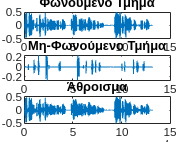

soundsc(sum_signal, fs);

% Απεικόνιση του αθροίσματος των δύο κυματομορφών
subplot(3,1,3);
plot(sum_signal);
title('Άθροισμα');

***γ) ***Στον κωδικά μας η κυματομορφή `y1` είναι η `voiced_signal` και η κυματομορφή `y2` είναι η `unvoiced_signal`.

Παρατηρούμε ότι τα κομμάτια που η y1 έχει 0 είναι τα σημέια που η y2 δεν έχει 0, και το αντίστροφο, το οποίο μας δείχνει ότι χωρίσαμε σωστά τα φωνούμενα και τα μη-φωνούμενα κομμάτια του αρχείου που μας δώθηκε.

Κατά την δημιουργία του αθροίσματος, βλέπουμε, ότι οι δύο μας κυματομορφές προστίθενται σωστά και δημιουργούν το αρχικό μας ήχο.

***Παρατηρήσεις:*** Η διαδικασία εισαγωγής μηδενικών unvoiced frames στην voiced κυματομορφή (και το αντίστροφο) είναι αρκετά σημαντική, διότι αν οι κυματομορφές μας είχαν διαφορετική διάρκεια, δεν θα μπορούσαν να προστεθούν.

***δ) ***Αλλάζοντας τις τιμές των a και b παρατηρούμε ότι επηρεάζεται το ποια κομμάτια θεωρούνται φωνούμενα και ποια μή-φωνούμενα, λογικό μιας και με την χρήση των a και b, επηρεάζεται δυναμικά η επιλογή των frames απο την σχέση: 

`unvoiced_frames = energy < a * max(energy) & zcr > b * max(zcr);`

`voiced_frames = ~unvoiced_frames;`

Οι τιμές a=b= 0.4, είναι μια αρκετά καλή λύση, γιατί έτσι δεν χάνεται πληροφορία του φωνούμενου τμήματος, στην μη-φωνούμενη κυματομορφή (και το αντίθετο).

#### 3. De-esser

O De-esser είναι μια εφαρμογή που χρησιμοποιείται στα προγράμματα μουσικής παραγωγής, ώστε να μειωθεί η ένταση των άφωνων φωνημάτων «ες» και «σσ» σε ηχογραφήσεις φωνητικών. Σκεφτείτε πως μπορείτε να εφαρμόσετε τον κώδικα που φτιάξατε στο προηγούμενο βήμα για να υλοποιήσετε ένα προσεγγιστικό σύστημα De-esser. Εφαρμόστε την μετατροπή του κώδικά σας στο αρχείο φωνητικών «vocals_deess.wav». Προσέξτε ότι ο ρυθμός δειγματοληψίας είναι στα 44.1 kHz κι έτσι το frame πρέπει να είναι λίγο μεγαλύτερο. Δοκιμάστε την τιμή frame=1024.

Χρησιμοποιώντας την ίδια λογική με τον κώδικα της άσκησης 2 φτιάξαμε τον παρακάτω κώδικα:

% Φόρτωση του αρχείου ήχου
[x, fs] = audioread('vocals_deess.wav');

% Παράμετροι frame και ovrlp
frame = 1024;  % Μεγαλύτερο frame για ρυθμό δειγματοληψίας 44.1 kHz
ovrlp = 0.5;

% Ανάλυση του ήχου σε frames
X = frame_wind(x, frame, ovrlp);

% Υπολογισμός ενέργειας και Zero-Crossing Rate για κάθε frame
energy = sum(X.^2);
zcr = sum((sign(X(2:end, :)) - sign(X(1:end-1, :))).^2);

% Παράμετροι a και b
a = 0.9;
b = 0.5;

% Χωρισμός των frames σε "σσ/ες" και όχι "σσ/ες"
unvoiced_frames = energy < a * max(energy) & zcr > b * max(zcr);
voiced_frames = ~unvoiced_frames;

% Εξασθένηση των "σσ/ες" frames
attenuation_factor = 0.5;  % Παράγοντας εξασθένησης (0.5 = 50%)
X(:, unvoiced_frames) = X(:, unvoiced_frames) * attenuation_factor;

% Ανασύνθεση των frames
deessed_signal = frame_recon(X, ovrlp);

% Αναπαραγωγή του αρχικού και του επεξεργασμένου σήματος
disp('Now hearing original signal');

Now hearing original signal


soundsc(x, fs);
pause(length(x) / fs + 1);
disp('Now hearing de-essed signal');

Now hearing de-essed signal


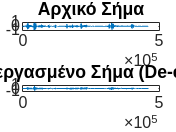

soundsc(deessed_signal, fs);

% Απεικόνιση των δύο σημάτων
figure;
subplot(2,1,1);
plot(x);
title('Αρχικό Σήμα');
subplot(2,1,2);
plot(deessed_signal);
title('Επεξεργασμένο Σήμα (De-essed)');

Βλέπουμε (και ακούμε) ότι στο επεξεργασμένο σήμα τα "σσ/ες" ακούγονται λιγότερο έντονα. Βέβαια, υπάρχει και άλλος ένας τρόπος για την δημιουργία ενός de-esser.

####  3. De-esser (alternate)

Παρακάτω παραθέτουμε έναν εναλλακτικό τρόπο χρησιμοποιώντας μετασχηματισμούς Fourier και στοχεύοντας απευθείας σε συγκεκριμένες συχνότητες.

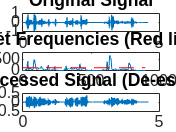

% --- Load and process the audio ---
[x, fs] = audioread('vocals_deess.wav');

% Parameters
frame = 1024;         % Frame size
ovrlp = 0.5;          % Overlap
threshold_factor = 0.18;
attenuation_factor = 0.33;
low_freq = 4000;      % Lower frequency for sibilance detection
high_freq = 8000;     % Upper frequency for sibilance detection

% Frame analysis with windowing
X = frame_wind(x, frame, ovrlp);

% Fourier Transform of each frame
Xf = fft(X);

% Convert frequencies to indices
low_index = round(low_freq / fs * frame) + 1;
high_index = round(high_freq / fs * frame) + 1;

% Calculate energy in the target frequencies
energy = sum(abs(Xf(low_index:high_index, :)), 1);

% Smooth energy with a moving average filter
energy = movmean(energy, 5);

% Set a dynamic threshold
threshold = threshold_factor * max(energy);

% Detect frames with sibilance
mask = energy > threshold;

% Attenuate sibilance in detected frames
Xf(:, mask) = Xf(:, mask) * attenuation_factor;

% Inverse Fourier Transform
X_dees = ifft(Xf, 'symmetric');

% Signal reconstruction
y_dees = frame_recon(X_dees, ovrlp);

% --- Plotting ---

figure;
subplot(3, 1, 1);
plot(x);
title('Original Signal');
xlabel('Frame');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(energy);
hold on;
plot([1, length(energy)], [threshold, threshold], 'r--');
hold off;
title('Energy in Target Frequencies (Red line is threshold)');
xlabel('Frame');
ylabel('Energy');
ylim([0, max(energy) * 1.2]);

subplot(3, 1, 3);
plot(y_dees);
title('Processed Signal (De-essed)');
xlabel('Frame');
ylabel('Amplitude');


% --- Listen to the results ---
disp('Now hearing original signal');

Now hearing original signal


soundsc(x, fs);
pause(length(x) / fs + 1);
disp('Now hearing de-essed signal');

Now hearing de-essed signal


soundsc(y_dees, fs);

#### 4. Αυτόματος Ανιχνευτής Ομιλίας (Voice Activity Detector – VAD)

α) Φορτώστε το αρχείο ήχου “guit2.wav” και αναλύστε το με την frame_wind με frame= 256 δείγματα, ovrlp = 0.5. Για κάθε frame που εξάγει η frame_wind υπολογίστε την Ενέργεια $E\left(k\right)$ σύμφωνα με τις σχέσεις της Άσκησης 2.

β) Απεικονίστε τη μεταβλητή Ε. Η μεταβλητή Ε σας δείχνει αν κάποιο frame περιέχει ομιλία ή όχι. Μπορείτε να βγάλετε έναν κανόνα (κριτήριο) που θα σας λέει πότε έχετε ενεργή ομιλία;

γ) Δημιουργήστε έναν πίνακα Υ ιδίων διαστάσεων με τον Χ της frame_wind. Αν έχετε ενεργή ομιλία στο συγκεκριμένο frame, τότε αντιγράψτε την αντίστοιχη στήλη του Χ στον Υ.

δ) Χρησιμοποιώντας τη “frame_recon.m”, ανασυγκροτήστε την κυματομορφή y από τον πίνακα Υ. Ακούστε την κυματομορφή y. Τί παρατηρείτε;

ε) Υπολογίστε το ποσοστό των συνολικών frames που είναι ανενεργά. Σε ένα κινητό τηλέφωνο, το κινητό κλείνει τον πομπό του την ώρα των ανενεργών χρόνων, κάνοντας έτσι οικονομία στη μπαταρία του. Άρα το ποσοστό που υπολογίσατε προηγουμένως δείχνει περίπου το ποσοστό της ενέργειας που κάνει οικονομία ένα κινητό τηλέφωνο.

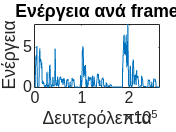

% Φόρτωση του αρχείου ήχου
[x, fs] = audioread('guit2.wav');

% Παράμετροι frame και ovrlp
frame = 256;
ovrlp = 0.5;

% Ανάλυση του ήχου σε frames
X = frame_wind(x, frame, ovrlp);

% Υπολογισμός της ενέργειας για κάθε frame
E = sum(X.^2);

% Απεικόνιση της μεταβλητής Ε
figure;
plot((1:length(E)) * frame, E);
xlabel('Frames');
ylabel('Ενέργεια');
title('Ενέργεια ανά frame');


% Θέτουμε κατώφλι για να κρίνουμε εάν υπάρχει ομιλία σε ένα frame
threshold = 0.05;

% Δημιουργία του πίνακα Υ με τα ενεργά frames
Y = X(:, E > threshold);

% Ανασύνθεση του ήχου από τον πίνακα Υ
y = frame_recon(Y, ovrlp);

% Αναπαραγωγή του ανακατασκευασμένου ήχου
soundsc(y, fs);

% Υπολογισμός του ποσοστού ανενεργών frames
inactive_frames_percentage = sum(E <= threshold) / length(E) * 100;
disp(['Το ποσοστό των ανενεργών frames είναι: ' num2str(inactive_frames_percentage) '%']);

Το ποσοστό των ανενεργών frames είναι: 33.139%


***β)*** Παρατηρούμε ότι όταν το frame δεν έχει ομιλία, η ενέργειά του είναι μηδενική, επομένως ο κανόνας μας είναι οτι υπάρχει ομιλία μόνο οπου υφίσταται $E\left(k\right)>0$.

***δ)*** Ακούγοντας την ανασυγκροτημένη κυματομορφή, παρατηρούμε ότι όλα τα κομμάτια κατά τα οποία δεν υπάρχει ομιλία έχουν εξαφανιστεί και έτσι η διάρκεια του αρχείου ήχου, έχει μειωθεί (κατά 33.139%) όπως θα δούμε στο παρακάω ερώτημα.

***Παρατηρήσεις:*** Το threshold που χρησιμοποιούμε είναι 0.05, έπειτα από δοκιμές και επιλέχθηκε ώστε να μην χάνουμε πληροφορία κατά την διάρκεια ανενεργών frames.

#### 5. Ανιχνευτής onset μουσικών νοτών

α) Φορτώστε το αρχείο ήχου “piano.wav” και αναλύστε το με την frame_wind με frame = 256 δείγματα, ovrlp = 0.5. Για κάθε frame που εξάγει η frame_wind υπολογίστε την Ενέργεια $E\left(k\right)$ σύμφωνα με τις σχέσεις της Άσκησης 2.

β) Υπολογίστε και απεικονίστε τη μεταβλητή:


$$\delta E\left(k\right)=\left|E\left(k\right)-E\left(k-1\right)\right|$$


γ) Επινοείστε ένα κριτήριο για να εντοπίστε την αρχή (onset) κάθε μουσικής νότας.

δ) Δημιουργήστε τον πίνακα Ζ, του οποίου οι στήλες είναι 1 αν αντιστοιχούν σε onset και 0 στην αντίθετη περίπτωση. Χρησιμοποιήστε τη frame_recon για να ανακατασκευάσετε την z από το Ζ και ακούστε το αποτέλεσμα. Το αποτέλεσμα στη μουσική θεωρία λέγεται ρυθμικό σολφέζ.

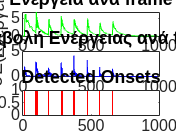

% Φόρτωση του αρχείου ήχου
[x, fs] = audioread('piano.wav');

% Παράμετροι frame και ovrlp
frame = 256;
ovrlp = 0.5;

% Ανάλυση του ήχου σε frames
X = frame_wind(x, frame, ovrlp);
E = sum(X.^2);

% Υπολογισμός της μεταβολής της ενέργειας
dE = abs(diff(E, 1, 2));

% Ορισμός threshold για τον εντοπισμό των onset
threshold = 1.5;
onsets = dE > threshold;

% Δημιουργία του πίνακα Ζ
Z = zeros(size(X, 2), 1);
Z(onsets) = 1;

% Απεικόνιση της μεταβολής της ενέργειας
figure;
subplot(3, 1, 1);
plot(1:length(E), E, 'g');
xlabel('Frame');
ylabel('Ενέργεια');
title('Ενέργεια ανά frame');

subplot(3, 1, 2);
plot(1:length(dE), dE, 'b');
xlabel('Frame');
ylabel('\deltaE(k)');
title('Μεταβολή Ενέργειας ανά frame');

% Απεικόνιση των onsets
subplot(3, 1, 3);
stem(1:length(Z), Z, 'r', 'Marker', 'none');
xlabel('Frame');
ylabel('Onset');
title('Detected Onsets');


% Ανασύνθεση του ήχου z από τον πίνακα Ζ
z = frame_recon(X(:, Z == 1), ovrlp);

% Ακρόαση του ανασυνθεσμένου ήχου
soundsc(z, fs);

***γ)*** Το κριτήριο που επιλέχθηκε για τον εντοπισμό της αρχής (onset) κάθε μουσικής νότας είναι η χρήση threshold τιμής. Σύμφωνα με τον κανόνα που εφαρμόσαμε, αν η διαφορά ενέργειας είναι μεγαλύτερη από την τιμή του κατωφλιού ($\delta E\left(k\right)>\textrm{threshold}$) τότε το παρόν frame είναι onset. 

***Παρατηρήσεις: ***Βέβαια, η χρήση threshold μας δημιούργησε ένα πρόβλημα, διότι υπήρχαν φορές, όπου η $\delta E\left(k\right)$ ήταν το ίδιο μεγάλη στην ίδια νότα (όπως βλέπουμε έντονα στην 2η νότα της οκτάβας) παραπάνω από μια φορές, με αποτέλεσμα να εμφανίζονται πολλαπλά frames, με onset σε μια νότα.

#### 5. Ανιχνευτής onset μουσικών νοτών (alternate)

Για να λύσουμε το παραπάνω πρόβλημα αποπειραθήκαμε να αξιοποιήσουμε υψηδιαβατό φίλτρο (high-pass filter) και συχνότητα αποκοπής (cutoff frequency), πριν χρησιμοποιήσουμε το threshold.

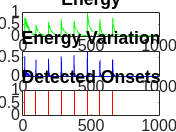

% Load the audio file
[x, fs] = audioread('piano.wav');

% Define the filter parameters
cutoff_frequency = 1100; % Hz
filter_order = 8;

% Design a high-pass filter
[b, a] = butter(filter_order, cutoff_frequency/(fs/2), 'high');

% Apply the filter to the audio signal
x_filtered = filter(b, a, x);

% Define frame parameters
frame_length = 256;
overlap = 0.5;

% Analyze the audio using frame_wind
X = frame_wind(x_filtered, frame_length, overlap);
E = sum(abs(X).^2, 1); % Sum along the rows (dimension 1) to get energy for each frame

% Compute energy variation
dE = abs([0, diff(E)]); % Use comma instead of semicolon to create a row vector

% Define a threshold for onset detection
threshold = 0.35;
onsets = dE > threshold;

% Create the Z matrix
Z = zeros(size(X, 2), 1);
Z(onsets) = 1;

% Reconstruct the audio signal z from Z
z = frame_recon(X(:, Z == 1), overlap);

% Plot the energy variation and detected onsets
figure;

subplot(3, 1, 1);
plot(1:length(E), E, 'g');
xlabel('Frame');
ylabel('Energy');
title('Energy');

subplot(3, 1, 2);
plot(1:length(dE), dE, 'b');
xlabel('Frame');
ylabel('\deltaE(k)');
title('Energy Variation');

subplot(3, 1, 3);
stem(1:length(Z), Z, 'r', 'Marker', 'none');
xlabel('Frame');
ylabel('Onset');
title('Detected Onsets');


% Listen to the reconstructed audio
soundsc(z, fs);

***Παρατηρήσεις: ***Βέβαια, κατά την ανακατασκευή του ήχου, έχουμε 8 frames το ένα μετά το άλλο, το οποίο σημαίνει ότι ο τελικός μας ήχος είναι στιγμιαίος και δεν βγάζει ιδιαίτερο νόημα. Μπορεί να καταλάβαμε κάτι διαφορετικό στην εκφώνηση και να κάναμε λάθος, αλλα φαινεται αρκετά σωστό.

Συγκρίνοντας, την Μεταβολή Ενέργειας ανάμεσα σε αυτό τον τρόπο και τον παραπάνω, φαίνεται ότι με την χρήση των φίλτρων, το αποτέλεσμα είναι πιο ξεκάθαρο.